# ROS連携による学習画像の収集

Robotics System Toolboxで提供するROS連携機能でGzebo上の仮想カメラから学習画像を収集する。対象のワークの位置姿勢はGazeboとのCommunicatorを使って取得する。

## 初期化

clear; close all force; clc;

## ROSに接続

rosshutdown;

Shutting down global node /matlab_global_node_03236 with NodeURI http://192.168.115.1:57025/


rosinit('192.168.115.130','NodeHost','192.168.115.1');

Initializing global node /matlab_global_node_05788 with NodeURI http://192.168.115.1:52204/


## 画像を取得するためのサブスクライバーを定義

imSub = rossubscriber('/kinect2/sd/image_color');
receive(imSub); % ダミー読み出し

## 取得した画像の可視化

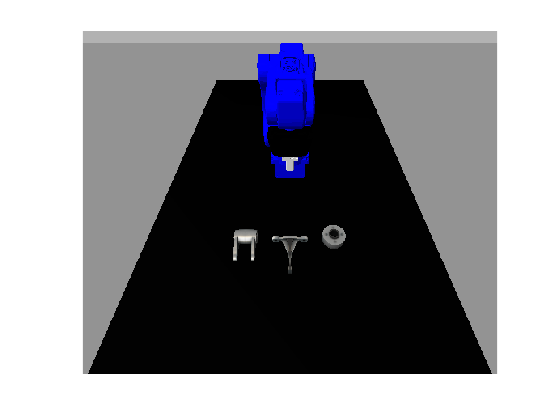

testIm = readImage(receive(imSub));
figure, imshow(testIm);

## Kinect2の姿勢を取得

rostfを使ってロボットのベース(world)からKinect2の座標変換行列を取得

tftree = rostf;
pause(1);
tf = getTransform(tftree,'world','kinect2_rgb_optical_frame');
% ここでの'world'はロボットのベース座標を指すことに注意。
% Gazeboのワールド座標系ではない。

% tfオブジェクトから変換行列を作成
tr = tf.Transform.Translation;
quat = tf.Transform.Rotation;
p = [tr.X tr.Y tr.Z];
q = [quat.W, quat.X, quat.Y, quat.Z];
rotm = quat2rotm(q);

% ワールド座標系原点からロボットアームの
% 原点フレーム(world)へのオフセットを追加
p(3) = p(3) + 1.02;

## Kinect2の内部パラメーターと外部パラメータを計算

horizontal_fov = 84.1*pi/180.0;
width = size(testIm,2);
height = size(testIm,1);
f = width/(2*tan(horizontal_fov/2));
IntrinsicMatrix = [f 0 0; 0 f 0; width/2 height/2 1];
cameraParams = cameraParameters('IntrinsicMatrix',IntrinsicMatrix);
[rotMat,trVec] = cameraPoseToExtrinsics(rotm',p);

## Gazeboの物理エンジンの設定変更

% Gazeboの設定変更のAPIオブジェクトを作成
gazebo = ExampleHelperGazeboCommunicator();

% 物理エンジンのタイムステップを増やす(=高速化される)
realTimeFactor = 10;
pauseSim(gazebo);
phys = readPhysics(gazebo);
phys.TimeStep = realTimeFactor/phys.UpdateRate;
setPhysics(gazebo,phys);
resumeSim(gazebo);

## オブジェクトを回転させながら学習画像を取得

Gazebo上のボールの位置や姿勢をMATLABから変更可能

% 画像の保存フォルダ
load('DemoDir');
imDir =  fullfile(DemoDir,'Source','ObjectDetector','trainingData');
winopen(imDir)
[~,~,~] = mkdir(imDir);

% 表示用のプレイヤー
videoPlayer = vision.DeployableVideoPlayer;

% ワークのオブジェクト名
targets = {'arm_part','t_brace_part','disk_part'};

% ワークを囲む3Dのバウンディングボックス
bboxes = [-0.05 0.05 -0.07 0.03 -0.01 0.04;
    -0.02 0.11 -0.06 0.06 -0.01 0.02;
    -0.04 0.04 -0.04 0.04 -0.01 0.03];

% ワークの把持点を定義
pickPts = cat(3,[-0.03 0 0.02; 0.03 0 0.02],...
    [0.01 0 0.01; 0.05 0 0.01],...
    [-0.02 0 0.01; 0.02 0 0.01]);

% 3Dバウンディングボックスを頂点座標に変換
vertices = zeros(8,3,3);
for k = 1:numel(targets)
    [xrange,yrange,zrange] = meshgrid(bboxes(k,1:2),bboxes(k,3:4),bboxes(k,5:6));
    vertices(:,:,k) = [xrange(:),yrange(:),zrange(:)];
end

% ワークの初期位置姿勢を取得し、保持
% (定位置から落下させて学習データをつくるため)
posOrg = zeros(numel(targets),3);
oriOrg = zeros(numel(targets),3);
for l = 1:numel(targets)
    model = ExampleHelperGazeboSpawnedModel(targets{l},gazebo);
    [pos, ori, vel] = getState(model);
    posOrg(l,:) = pos;
    oriOrg(l,:) = ori;
end
posOrg(:,3) = posOrg(:,3) + 0.1; % 高さをつけて落とす
velocity.Linear = [0,0,0];
velocity.Angular = [0,0,0];

% 回転のパターンを生成
numAngles = 128-1;
angles = linspace(0,2*pi,numAngles+1);
[r,p,y] = meshgrid(0,0,angles);
r = r(:); p = p(:); y = y(:);

% 姿勢のground truth保存用table
groundTruthPoses = table;

% 姿勢を変えながら学習データを生成
for k = 1:numel(r)
    % 姿勢を変える
    orientation = [r(k), p(k), y(k)];
    for l = 1:numel(targets)
        model = ExampleHelperGazeboSpawnedModel(targets{l},gazebo);
        setState(model,'position',posOrg(l,:),...
            'velocity',velocity,...
            'orientation',orientation);
    end
    
    % 姿勢が収束するまで待つ
    pause(5);
    
    % 画像を取得
    testIm = readImage(receive(imSub));
    testImOut = testIm;
    
    % 姿勢を取得
    bboxesImg = zeros(numel(targets),4);
    positions = zeros(numel(targets),3);
    orientations = zeros(numel(targets),3);
    for l = 1:numel(targets)
        model = ExampleHelperGazeboSpawnedModel(targets{l},gazebo);
        [pos, ori, vel] = getState(model);
        positions(l,:) = pos;
        orientations(l,:) = ori;
    end
    
    % 取得した姿勢から3Dバウンディングボックスの頂点座標を計算
    % また、2Dのバウンディングボックスに射影
    for l = 1:numel(targets)
        vert = positions(l,:) + vertices(:,:,l)*(eul2rotm(deg2rad(orientations(l,:)))');
        imagePoints = worldToImage(cameraParams,rotMat,trVec,vert);
        picPtsInWld = positions(l,:) + pickPts(:,:,l)*(eul2rotm(deg2rad(orientations(l,:)))');
        pickPtsInImg = worldToImage(cameraParams,rotMat,trVec,picPtsInWld);
        minPts = min(imagePoints);
        maxPts = max(imagePoints);
        bbox = [minPts maxPts-minPts];
        bboxesImg(l,:) = bbox;
        testImOut = insertMarker(testImOut,imagePoints);
        testImOut = insertShape(testImOut,'rectangle',bbox);
        testImOut = insertShape(testImOut,"Line",reshape(pickPtsInImg',1,[]),...
            "LineWidth",2,"Color",'red');
    end
    
    % 真値を保存
    groundTruthPoses = [groundTruthPoses;
        table(bboxesImg,positions,orientations)];
    
    pause(1);
    
    % 取得した画像とバウンディングボックスを可視化
    videoPlayer(testImOut);
    
    % 画像を保存
    imwrite(testIm,fullfile(imDir,['image_' sprintf('%05d',int32(k)) '.png'])); % 保存するとき
end
figure, imshow(testImOut);
save(fullfile(imDir,'groundTruthPoses.mat'),...
    'groundTruthPoses','cameraParams','bboxes','pickPts','rotMat','trVec');

## 取得画像の表示

イメージブラウザで画像確認 色のしきい値アプリケーションを起動して 単純なしきい値によるセグメンテーションを試す

imageBrowser(imDir);

Copyright (c) 2019, MathWorks, Inc.